clc;
clear all;
rng(1,"twister");

We want to Generate the random point with all the anchors

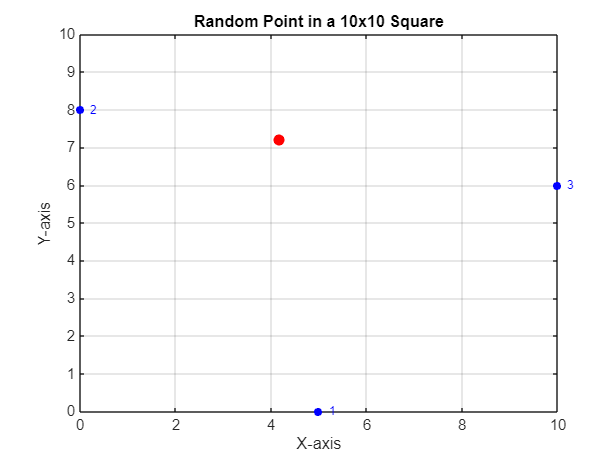

P = rand(2,1) * 10; 
Anc = [5, 0, 10;
       0, 8, 6];

% Create the plot
figure(1);
clf 
plot(P(1), P(2), 'ro', 'MarkerSize', 7, 'MarkerFaceColor', 'r'); % Plot the random point
hold on
plot(Anc(1,:), Anc(2,:), 'bo', 'MarkerSize', 5, 'MarkerFaceColor', 'b'); % Plot the Anc points

% Add text labels near the Anc points
for i = 1:size(Anc, 2)
    text(Anc(1,i) + 0.2, Anc(2,i), num2str(i), 'Color', 'blue', 'FontSize', 8); % Adjust the position and color as needed
end

xlim([0 10]);
ylim([0 10]);
grid on;
xlabel('X-axis');
ylabel('Y-axis');
title('Random Point in a 10x10 Square');


% Getting the measurements
c = 299792458; 
w = 1e-1;
w1 = w * randn(1);
w2 = w * randn(1);
w3 = w * randn(1);

om1 = c * w1^2;
om2 = c * w2^2;
om3 = c * w3^2;

% Vettore di misurazioni pulite
p1 = norm(Anc(:,1) - P);
p2 = norm(Anc(:,2) - P);
p3 = norm(Anc(:,3) - P);

% Misure rumorose
p1b = p1 + w1;
p2b = p2 + w2;
p3b = p3 + w3;

### Metodo 1: Non-Lin sol

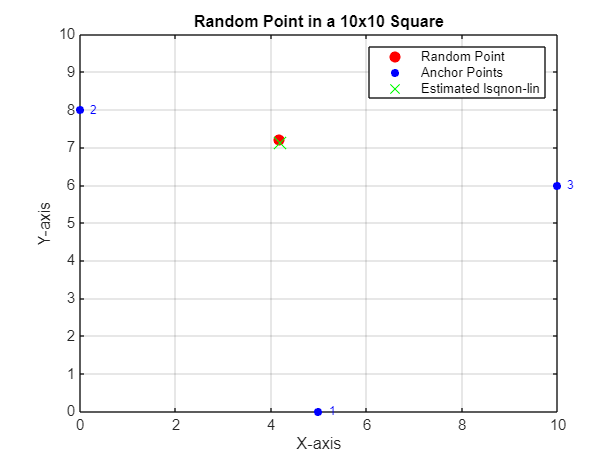

% Usiamo il metodo del non linear weighted least squares method

rand(1); % per controllare seed 
fun = @(r) 1e5*[(p1b - norm(r - Anc(:,1))) / om1;
            (p2b - norm(r - Anc(:,2))) / om2;
            (p3b - norm(r - Anc(:,3))) / om3];

% Setting options for the least squares solver
options = optimoptions('lsqnonlin', 'Algorithm', 'levenberg-marquardt', 'Display', 'off','FunctionTolerance', 1e-7, 'MaxIterations', 1000);
x = lsqnonlin(fun, [0;0], [0,0], [10,10], options);
Residual1 =norm(P-x);
% Plot the estimated point. Risulta essere sovrapposto
plot(x(1), x(2), 'gx', 'MarkerSize', 12, 'MarkerFaceColor', 'g'); 

legend('Random Point', 'Anchor Points', 'Estimated lsqnon-lin');



disp('Actual Point:');

Actual Point:


disp(P);

    4.1702
    7.2032



disp('Estimated Point:');

Estimated Point:


disp(x);

    4.1916
    7.1298



### Metodo 2: Least square on Linearized version of measurements

Proviamo senza mettere il constarint, senza proprio

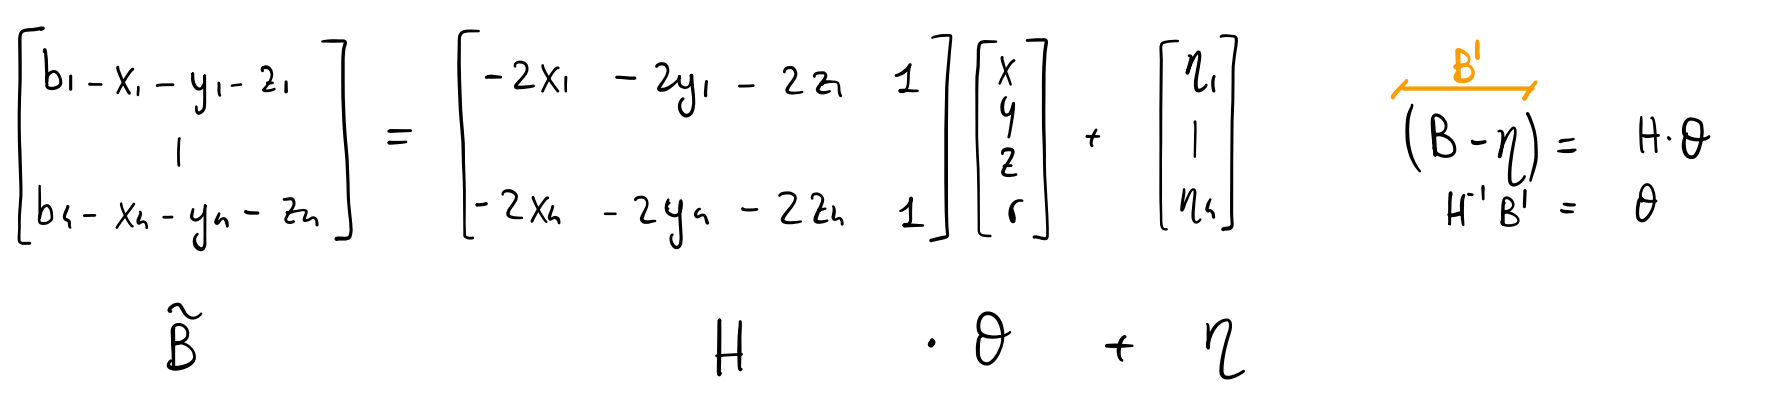

Bm = [p1b^2 - Anc(1,1)^2 - Anc(2,1)^2;
      p2b^2 - Anc(1,2)^2 - Anc(2,2)^2;
      p3b^2 - Anc(1,3)^2 - Anc(2,3)^2];
  
H =   [-2*Anc(1,1), -2*Anc(2,1), 1;
       -2*Anc(1,2), -2*Anc(2,2), 1;
       -2*Anc(1,3), -2*Anc(2,3), 1];
      
n = [2*p1b*w1;
     2*p2b*w2;
     2*p3b*w3];

% Riscriviamo ora in B'
B_prime = Bm - n;

% Solve the least squares problem H*theta = B_prime
theta = pinv(H) * B_prime; % Alternatively, use theta = pinv(H) * B_prime;

% Display the result
disp('The solution is:');

The solution is:


disp(theta);

    4.1700
    7.2035
   69.2697



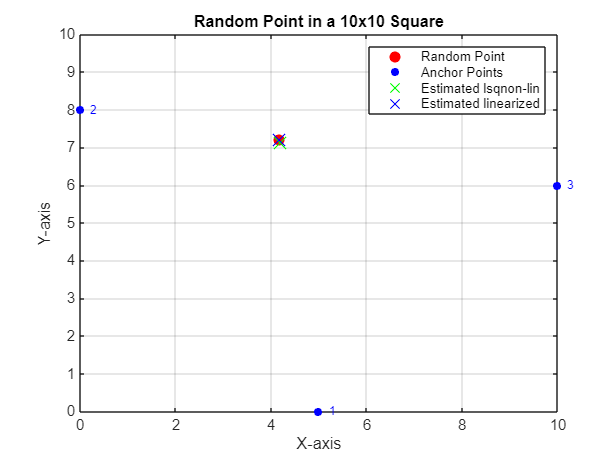

plot(theta(1), theta(2), 'bx', 'MarkerSize', 12, 'MarkerFaceColor', 'b'); 

legend('Random Point', 'Anchor Points', 'Estimated lsqnon-lin','Estimated linearized ');
hold off;


theta

theta =     4.1700
    7.2035
   69.2697


P

P =     4.1702
    7.2032


r = P(1,1)^2 + P(2,1)^2

r = 69.2775

Residual2 = norm(theta(1:2,:)-P)

Residual2 = 3.4825e-04

### Metodo 2.2: Least square on Linearized version of measurements, CONSTRAINED

% Definiamo la funzione obiettivo che vogliamo minimizzare
objective = @(theta) norm(H * theta - B_prime)^2;

% Define the non-linear constraint
nonlcon = @(theta) deal([], theta(3) - theta(1)^2 - theta(2)^2);


% Options for fmincon
options = optimoptions('fmincon', 'Display', 'off');

% Solve the constrained optimization problem
theta = fmincon(objective, [0; 0; 0], [], [], [], [], [], [], nonlcon, options);

% Display the result
disp('The solution is:');

The solution is:


disp(theta);

    4.1700
    7.2028
   69.2698




Residual3 = norm(theta(1:2,:)-P)

Residual3 = 4.6433e-04

### Metodo 3: Least square on Linearized version of measurements, UN-CONSTRAINED

B_un = [(p1b^2 - p2b^2 -Anc(1,1)^2 + Anc(1,2)^2 - Anc(2,1)^2 + Anc(2,2)^2);
        (p2b^2 - p3b^2 -Anc(1,2)^2 + Anc(1,3)^2 - Anc(2,2)^2 + Anc(2,3)^2);]

B_un =    73.3855
   54.6610


n_un = [2*p1b*w1-2*p2b*w2;2*p2b*w2-2*p3b*w3];
B_unP = B_un-n_un

B_unP =    73.5563
   54.5863



H = [-2*(Anc(1,1)-Anc(1,2)),-2*(Anc(2,1)-Anc(2,2));
     -2*(Anc(1,2)-Anc(1,3)),-2*(Anc(2,2)-Anc(2,3));]

H =    -10    16
    20    -4



theta = inv(H)* B_unP

theta =     4.1700
    7.2035


P

P =     4.1702
    7.2032


Residual4 = norm(theta-P);

## Comparing results

Residual1,Residual2,Residual3,Residual4

Residual1 = 0.0765

Residual2 = 3.4825e-04

Residual3 = 4.6433e-04

Residual4 = 3.4825e-04

9e-2

1e-1